# Laborator 5

## Problema 1

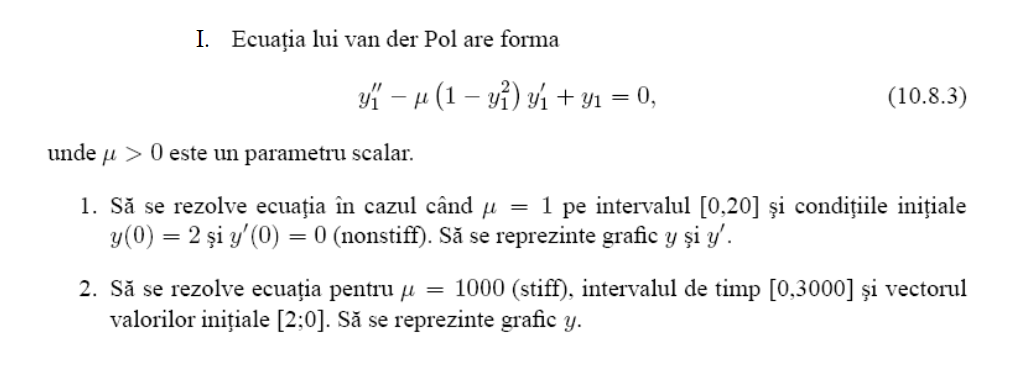

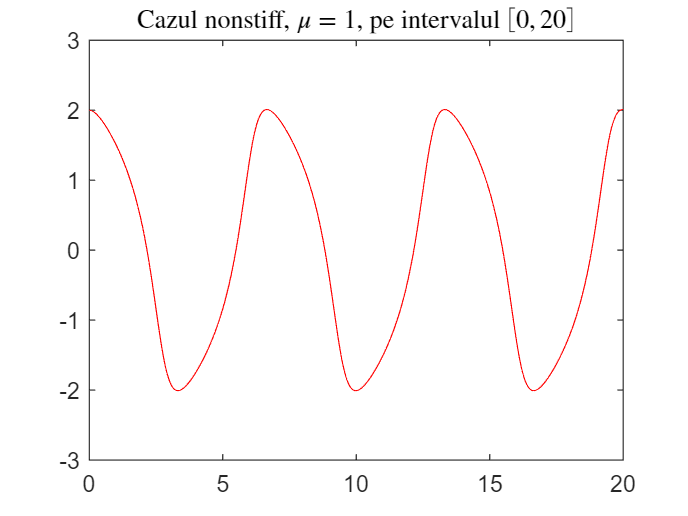

%Ecuatia van der Pol
%y''-miu*(1-y^2)*y'+y=0
%y(0)=2
%y'(0)=0
%Scriem ecuatia sub forma de sistem:
%y1=y
%y2=miu*(1-y1^2)*y2-y1
%y1(0)=0
%y2(0)=0

%nonstiff
a=0;b=20;%capetele intervalului de integrare
miu=1;%parametrul miu

y0=[2,0];%conditiile initiale
options=odeset('RelTol',1e-8);%modificarea optiunilor
[t,y]=ode45('fVanDerPol',[a,b],y0,options,miu);%apelarea rezolvitorului
figure(1)
plot(t,y(:,1),'r');
title('Cazul nonstiff, $\mu = 1$, pe intervalul $[0, 20]$','interpreter', 'latex')

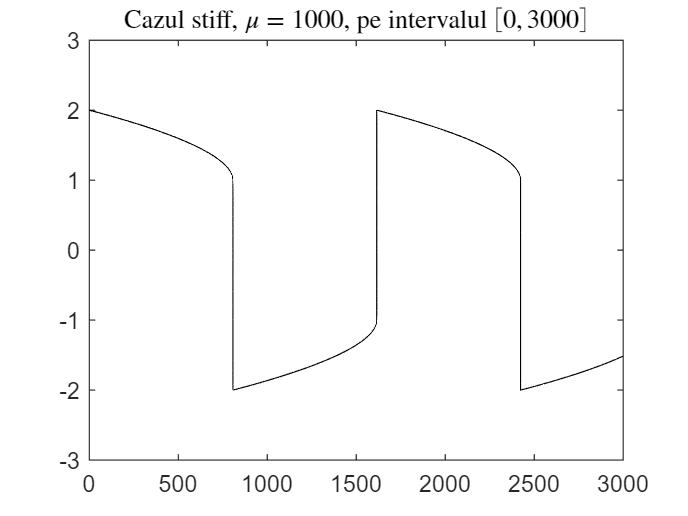


%tot stiff
a=0;b=3000;%capetele intervalului de integrare
miu=1000;%parametrul miu
y0=[2,0];%conditiile initiale
options=odeset('RelTol',1e-3);%modificarea optiunilor
[t1,y1]=ode23s('fVanDerPol',[a,b],y0,options,miu);%apelarea rezolvitorului
figure(3)
plot(t1,y1(:,1),'k');
title('Cazul stiff, $\mu = 1000$, pe intervalul $[0, 3000]$','interpreter', 'latex')

## Problema 2

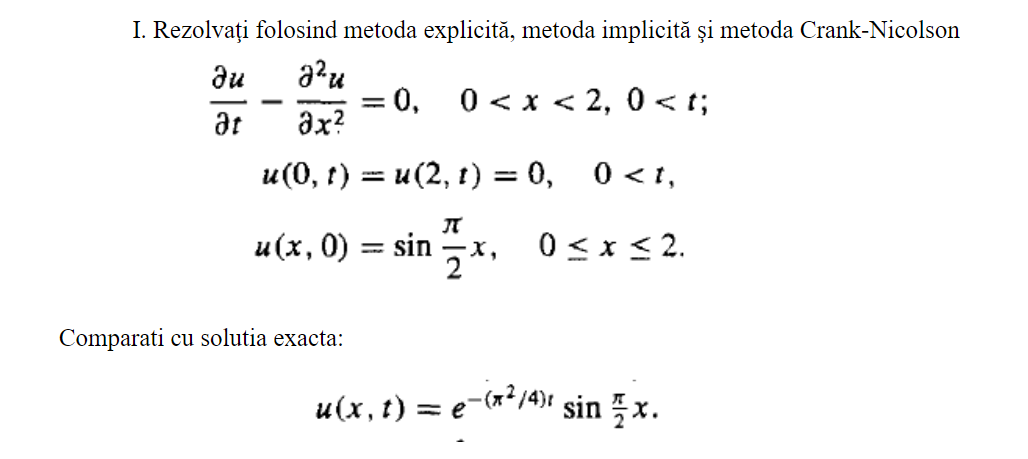

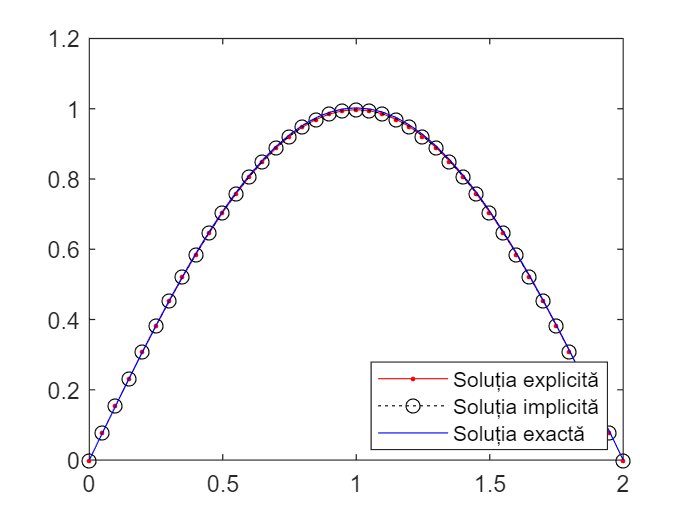

dt=0.001;
dx=0.05;
Nx=2/(dx)+1;
x=0:dx:2;
tf=dt;
Nt=tf/dt;

Uo=sin(pi/2*x);

Un=zeros(Nx,1);
%explicit
n=0;
while (n<Nt) 
    n=n+1;
    for i=2:Nx-1
    Un(i)=Uo(i)+dt/(dx*dx)*(Uo(i-1)-2*Uo(i)+Uo(i+1));
    end
    Uo=Un;
end

plot(x,Uo,'.-r')
hold on

Uo=sin(pi/2*x);

%implicit
A=zeros(Nx,Nx);b=zeros(Nx,1);
niu=dt/(dx*dx);
n=0;
while (n<Nt) 
    n=n+1;
    
    A(1,1)=1;b(1)=0;
    %matricea
    for i=2:Nx-1
    A(i,i-1)=-niu;A(i,i)=1+2*niu;A(i,i+1)=-niu;b(i)=Uo(i);
    end
    A(Nx,Nx)=1;b(Nx)=0;
    
    Un=A\b;
    Uo=Un;
end

plot(x,Uo,'o:k')
hold on

%solutia analitica
U=HeatAnalytic(x,tf);
plot(x,U,'b')

legend('Soluția explicită', 'Soluția implicită','Soluția exactă', 'Location','best')